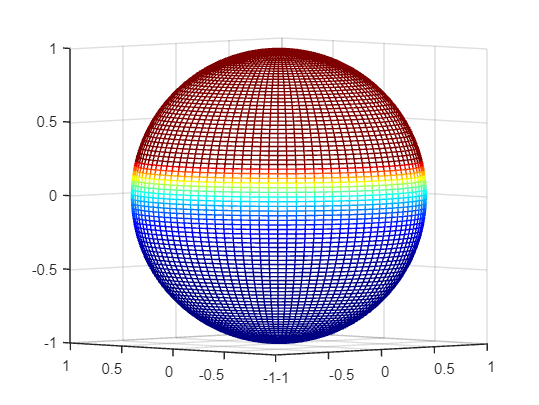

ans =   Figure (24) - 属性:

      Number: 24
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


Qfunction([1 0 0 0 0 0]')

scalar_product([1 0 0 0 0 1]' ,spin_coherent(pi/2,0));

function f1=Qfunction(state)
    f1=figure;
    m=100;n=100;
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi];
    for i=1:length(theta_list)
        theta=theta_list(i);
        for j=1:length(phi_list)
            phi=phi_list(j);
            Qfunction_result(i,j)=scalar_product(state,spin_coherent(theta,phi));
        end
    end
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,Qfunction_result');
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    daspect([1 1 1]);
    colormap jet
    clim([0 0.1])
end
function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end
function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
function result=scalar_product(state1,state2)
    result=abs(ctranspose(state1)*state2).^2;
end